% Preformance envelope calculation for dhc6 twin otter.
% This is the MATLAB version

clear all;
clf;

% Aircraft data and ISA
Weight=264550;   %lb
T=4*56750;
T0=518.7;
g=32.174;
R=1716;
S=3779.3;
rho0=0.002377;
L=0.003566;
P0=2116.2;
gamma=1.4;
Clmax=1.7;
K11 = 0.88

K11 = 0.8800

K22 = -0.016

K22 = -0.0160

K33 = -0.3

K33 = -0.3000

K44 = 0

K44 = 0

BPR = 4.85

BPR = 4.8500

c0=0.359

c0 = 0.3590

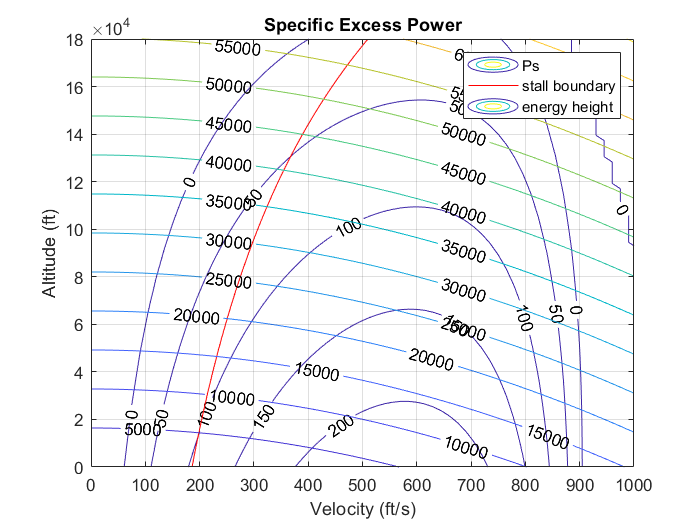


%Altitude and Velocity range
h=[0.:2250:180000.];
V=[0.:15:1200];

for i=1:81,
 alt=h(i)*0.3048;
 temp=T0-alt*L;
 press=P0*(temp/T0)^(g/L/R);
 rho=press/(R*temp);;
 a=sqrt(gamma*R*temp);
 for j=1:81,
  Vel=V(j);
  M=Vel/a;
  sigma = rho/rho0;
  alpha = (((K11+K22*BPR+(K33+K44*BPR)*M))*sigma^0.7);
  Thrust=T*alpha;
  Cl=Weight/(0.5*rho*Vel*Vel*S);
  c=c0*(1-0.15*BPR^0.65)*(1+0.28*(1+0.063*BPR^2)*M)*sigma^0.08;
  if (M<0.99),
% compressibility correction
   beta=sqrt(1-M^2);
   Cd=(0.02+0.0425*Cl*Cl)/beta;
   D=Cd*(0.5*rho*Vel*Vel*S);
% Specific Excess Power
   Ps(i,j)=Vel/Weight*(Thrust-D);
  else
% program is not set to handle supersonic drag.
   Ps(i,j)=0;
  end;
  Fs(i,j) = Ps(i,j)/c/alpha;
% if (Cl>Clmax),
%stall boundary     
%  Ps(i,j)=0;
% end;
% Specific Energy
  he(i,j)=alt+Vel*Vel/2./g;
 end;
 %stall boundary
 vstall(i)=sqrt(Weight/Clmax/0.5/rho/S);
end;

figure(1);
[c1,h1]=contour(V,h,Ps,[0 50 100 150 200 250 300]);
clabel(c1,h1);
title('Specific Excess Power');
xlabel('Velocity (ft/s)');
ylabel('Altitude (ft)');

hold on;
plot (vstall,h,'-r');
contour(V,h,he,'ShowText','on','LevelStep',5000);
legend('Ps','stall boundary','energy height');
hold off;
axis([0 1000 0 180000]);
grid on;

## fs

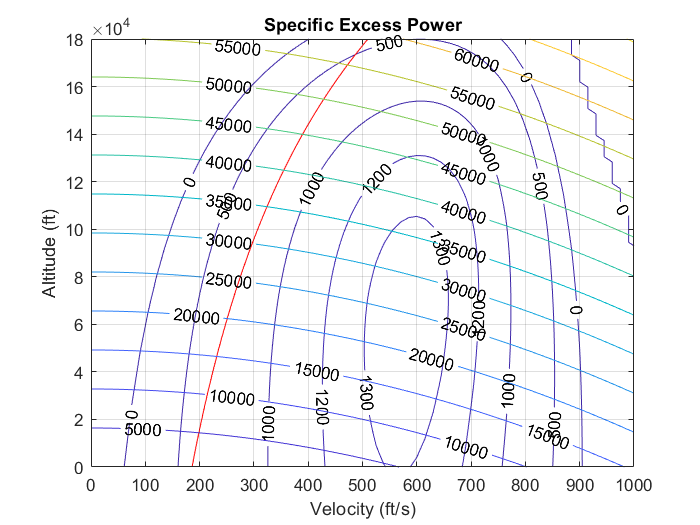

figure(2);
[c2,h2]=contour(V,h,Fs,[0 500 1000 1200 1300]);
clabel(c2,h2);
title('Specific Excess Power');
ylabel('Altitude (ft)');
xlabel('Velocity (ft/s)');
hold on
plot (vstall,h,'-r');
contour(V,h,he,'ShowText','on','LevelStep',5000);
axis([0 1000 0 180000]);
grid on;